# Assignment 13

# **Joint assimilation of navigation data coming from different sources**  

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

#### **Part I. Assimilation of GPS data only (absolute positioning)**

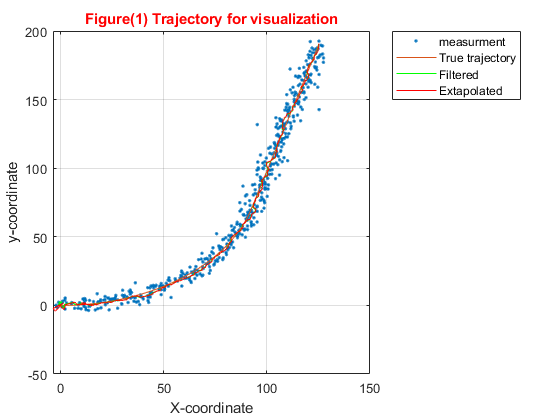

clear

m = 1;    % Extrapolation steps
N = 500;  % Number of points
NE = N-m; % Number of points for the extrapolation error
Mm = 500; % Number of runs

% Kalman errors initialization
ErrX = zeros(Mm,N);          % X true estimation error
ErrXE = zeros(Mm,NE);        % X-extrapolated true estimation error
ErrY = zeros(Mm,N);       % Y true estimation error
ErrYE = zeros(Mm,NE);     % Y-extrapolated true estimation error

for M = 1:Mm
    
    load('theta.mat')
    
    X = zeros(1,N);           % X-position
    Y = zeros(1,N);           % Y-position
    X(1) = 0;     % X initial value
    Y(1) = 0;     % Y initial value
    V = 10;       % velocity magnitude
    VX = zeros(1,N);          % X-Velocity
    VY = zeros(1,N);          % Y-Velocity
    VX(1) = V*cos(theta(1));     % X initial velocity
    VY(1) = V*sin(theta(1));     % Y initial velocity
    T = 0.05;        % Time step
    
    sigma_a = 1;      % Acceleration noise standard deviation
    
    normaldist = makedist('Normal',0,sigma_a);
    ax = random(normaldist,N,1);            % X-Acceleration noise
    
    normaldist = makedist('Normal',0,sigma_a);
    ay = random(normaldist,N,1);            % Y-Acceleration noise

    % Vectors generation
    for i = 2:N
        X(i) = X(i-1)+VX(i-1)*T+0.5*ax(i-1)*T^2;        % X vector generation
        VX(i) = V*cos(theta(i));                    % X Velocity generation
        Y(i) = Y(i-1)+VY(i-1)*T+0.5*ay(i-1)*T^2;        % Y vector generation
        VY(i) = V*sin(theta(i));                    % Y Velocity generation        
    end
    
        
    sigma_x = 3;           % X measurements noise standard deviation
    sigma_y = 3;        % Y measurements noise standard deviation

    normaldist = makedist('Normal',0,sigma_x);
    eta_x = random(normaldist,1,N);       % X measurements noise vector

    normaldist = makedist('Normal',0,sigma_y);
    eta_y = random(normaldist,1,N);       % Y measurements noise vector
    
    zx = X+eta_x;
    zy = Y+eta_y;

    Z = [zx;zy];                % measurments

    % Kalman filter parameters initialization
    Xi = [zx(2);(zx(2)-zx(1))/T;zy(2);(zy(2)-zy(1))/T];   % State vector
    P = (10^4)*eye(4);         % P matrix

    % state space matrices
    phi = [1 T 0 0;0 1 0 0;0 0 1 T;0 0 0 1];

    G = [0.5*T^2 0;T 0;0 0.5*T^2;0 T];
    
    sigma_a2 = 5;
    
    Q = G*G'*sigma_a2^2;
    
    R = [sigma_x^2 0;0 sigma_y^2];
    H = [1 0 0 0;0 0 1 0];
    % initial kalman gain
    K = P*H'/(H*P*H'+R);
    
    xi = zeros(N,1);
    yi = zeros(N,1);
    xiE = zeros(N,1);
    yiE = zeros(N,1);
    px = zeros(N,1);
    py = zeros(N,1);
    
    % Kalman filter
    for i = 3:N
        Xi = phi*Xi;
        P = phi*P*phi'+Q;
        
        Xi = Xi+K*(Z(:,i)-H*Xi);
        K = P*H'/(H*P*H'+R);
        P = (eye(4)-K*H)*P;
        XiE = Xi;

        for mm = m
            XiE = phi*XiE;     % Extrapolated state vector
        end
        
        xi(i) = Xi(1);
        yi(i) = Xi(3);
        xiE(i) = XiE(1);
        yiE(i) = XiE(3);
        px(i) = P(1,1);
        py(i) = P(3,3);

        % True estimation error calculation
        ErrX(M,i) = (Xi(1)-X(i))^2;
        ErrY(M,i) = (Xi(3)-Y(i))^2;

        % Extrapolation error calculation
        if i<(N+m-1)
            ErrXE(M,i) = (XiE(1)-X(i+m))^2;
            ErrYE(M,i) = (XiE(3)-Y(i+m))^2;
        end
    end
end


% Trajectory plotting for visualization
figure(1)
plot(zx,zy,'.',X,Y,xi,yi,'g',xiE,yiE,'r')
legend('measurment','True trajectory','Filtered','Extapolated','location','northeastoutside')
title('Figure(1) Trajectory for visualization','color','r')
xlabel('X-coordinate')
ylabel('y-coordinate')
grid on

**Comment:**

In the figure above, the true trajectory, the measurements, the Kalman filter estimation and extapolation with 1-step  ahead are graphed against each other. It can be seen that the estimation values are kind of following the trajectory with some disturbances.

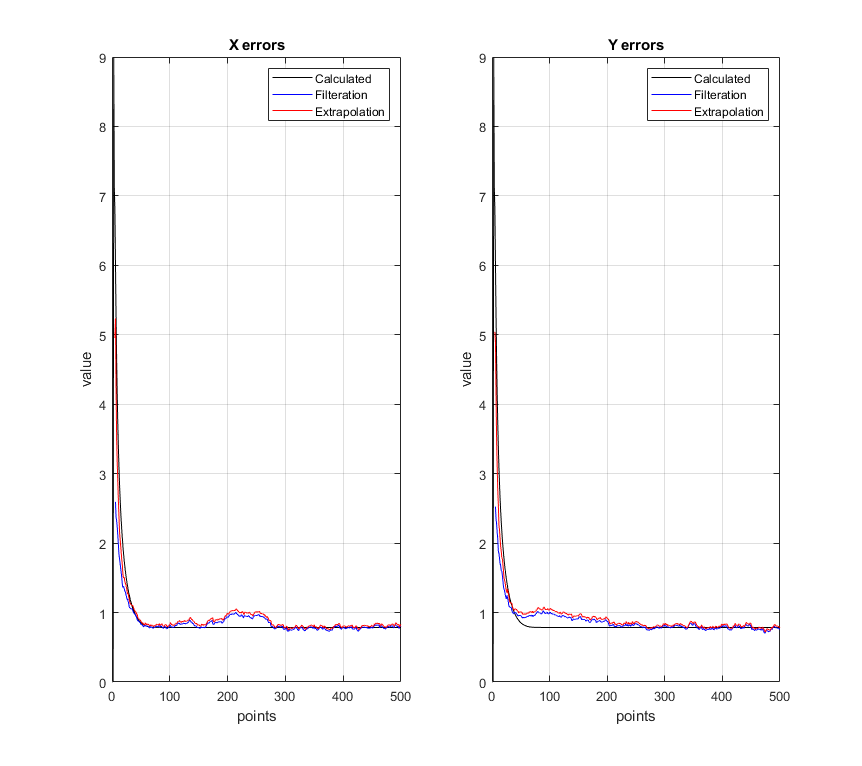

% plotting errors
figure(2)
subplot(1,2,1)
plotErr(ErrX,ErrXE,px,'X')
subplot(1,2,2)
plotErr(ErrY,ErrYE,py,'Y')

**Comment:**

In the figure shown above, for both X and Y positions,  true estimation errors of filteration and extrapolation are clearly approacing the calculated error settling at a value of ~0.78, slightly oscillating around it. The filter is quite effictive with these small errors. 

#### Part II. Assimilation of both GPS data (absolute positioning) and wheel odometry data (relative positioning).

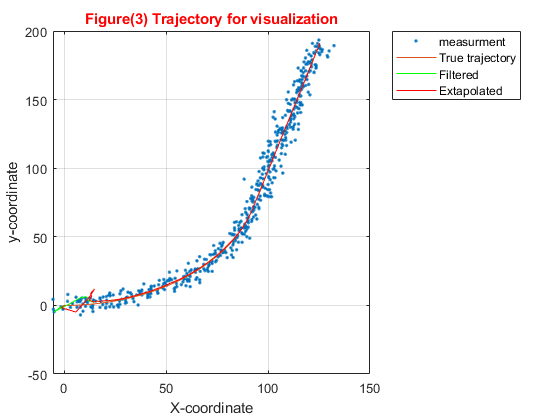

clear;

m = 1;    % Extrapolation steps
N = 500;  % Number of points
NE = N-m; % Number of points for the extrapolation error
Mm = 500; % Number of runs

% Kalman errors initialization
ErrX = zeros(Mm,N);          % X true estimation error
ErrXE = zeros(Mm,NE);        % X-extrapolated true estimation error
ErrY = zeros(Mm,N);       % Y true estimation error
ErrYE = zeros(Mm,NE);     % Y-extrapolated true estimation error

for M = 1:Mm
    
    load('theta.mat')
    
    X = zeros(1,N);           % X-position
    Y = zeros(1,N);           % Y-position
    X(1) = 0;     % X initial value
    Y(1) = 0;     % Y initial value
    V = 10;       % velocity magnitude
    VX = zeros(1,N);          % X-Velocity
    VY = zeros(1,N);          % Y-Velocity
    VX(1) = V*cos(theta(1));     % X initial velocity
    VY(1) = V*sin(theta(1));     % Y initial velocity
    T = 0.05;        % Time step
    
    sigma_a = 1;      % Acceleration noise standard deviation
    
    normaldist = makedist('Normal',0,sigma_a);
    ax = random(normaldist,N,1);            % X-Acceleration noise
    
    normaldist = makedist('Normal',0,sigma_a);
    ay = random(normaldist,N,1);            % Y-Acceleration noise

    % Vectors generation
    for i = 2:N
        X(i) = X(i-1)+VX(i-1)*T+0.5*ax(i-1)*T^2;        % X vector generation
        VX(i) = V*cos(theta(i));                    % X Velocity generation
        Y(i) = Y(i-1)+VY(i-1)*T+0.5*ay(i-1)*T^2;        % Y vector generation
        VY(i) = V*sin(theta(i));                    % Y Velocity generation        
    end
    
        
    sigma_x = 3;           % X measurements noise standard deviation
    sigma_y = 3;        % Y measurements noise standard deviation
    sigma_v = 0.5;           % V measurements noise standard deviation
    sigma_theta = 0.02;        % Theta measurements noise standard deviation

    normaldist = makedist('Normal',0,sigma_x);
    eta_x = random(normaldist,1,N);       % X measurements noise vector

    normaldist = makedist('Normal',0,sigma_y);
    eta_y = random(normaldist,1,N);       % Y measurements noise vector

    normaldist = makedist('Normal',0,sigma_v);
    eta_v = random(normaldist,1,N);       % V measurements noise vector

    normaldist = makedist('Normal',0,sigma_theta);
    eta_theta = random(normaldist,1,N);       % theta measurements noise vector
    
    zx = X+eta_x;
    zy = Y+eta_y;
    
    V_m = V+eta_v;
    theta_m = theta+eta_theta;

    Z = [zx;zy;V_m;theta_m];                % measurments

    % Kalman filter parameters initialization
    Xi = [zx(2);(zx(2)-zx(1))/T;zy(2);(zy(2)-zy(1))/T];   % State vector
    P = (10^4)*eye(4);         % P matrix

    % state space matrices
    phi = [1 T 0 0;0 1 0 0;0 0 1 T;0 0 0 1];

    G = [0.5*T^2 0;T 0;0 0.5*T^2;0 T];
    
    sigma_a2 = 5;
    
    Q = G*G'*sigma_a2^2;
    
    R = [sigma_x^2 0 0 0;0 sigma_y^2 0 0;0 0 sigma_v^2 0; 0 0 0 sigma_theta^2];
    
    sqV = sqrt(Xi(2)^2+Xi(4)^2);
    
    h = [Xi(1);Xi(3);sqrt(Xi(2)^2+Xi(4)^2);atan2(Xi(4),Xi(2))];
    hprime = [1 0 0 0;0 0 1 0; 0 Xi(2)/sqV 0 Xi(4)/sqV; 0 -Xi(4)/sqV 0 Xi(2)/sqV];
    
    K = P*hprime'/(hprime*P*hprime'+R);   % initial kalman gain
    
    xi = zeros(N,1);
    yi = zeros(N,1);
    xiE = zeros(N,1);
    yiE = zeros(N,1);
    px = zeros(N,1);
    py = zeros(N,1);
    
    % Kalman filter
    for i = 3:N
        Xi = phi*Xi;
        P = phi*P*phi'+Q;
        
        sqV = sqrt(Xi(2)^2+Xi(4)^2);
        sV = Xi(2)^2+Xi(4)^2;
        h = [Xi(1);Xi(3);sqrt(Xi(2)^2+Xi(4)^2);atan2(Xi(4),Xi(2))];
        hprime = [1 0 0 0;0 0 1 0; 0 Xi(2)/sqV 0 Xi(4)/sqV; 0 -Xi(4)/sV 0 Xi(2)/sV];
        
        Xi = Xi+K*(Z(:,i)-h);

        K = P*hprime'/(hprime*P*hprime'+R);
        P = (eye(4)-K*hprime)*P;
        
        XiE = Xi;

        for mm = m
            XiE = phi*XiE;     % Extrapolated state vector
        end
        
        xi(i) = Xi(1);
        yi(i) = Xi(3);
        xiE(i) = XiE(1);
        yiE(i) = XiE(3);
        px(i) = P(1,1);
        py(i) = P(3,3);

        % True estimation error calculation
        ErrX(M,i) = (Xi(1)-X(i))^2;
        ErrY(M,i) = (Xi(3)-Y(i))^2;

        % Extrapolation error calculation
        if i<(N+m-1)
            ErrXE(M,i) = (XiE(1)-X(i+m))^2;
            ErrYE(M,i) = (XiE(3)-Y(i+m))^2;
        end
    end
end

% Trajectory plotting for visualization
% Trajectory plotting for visualization
figure(3)
plot(zx,zy,'.',X,Y,xi,yi,'g',xiE,yiE,'r')
legend('measurment','True trajectory','Filtered','Extapolated','location','northeastoutside')
title('Figure(3) Trajectory for visualization','color','r')
xlabel('X-coordinate')
ylabel('y-coordinate')
grid on

**Comment:**

In the figure above, the true trajectory, the measurements, the Kalman filter estimation and extapolation with 1-step  ahead are graphed against each other. It can be seen that the estimation values are kind of following the trajectory with some disturbances.

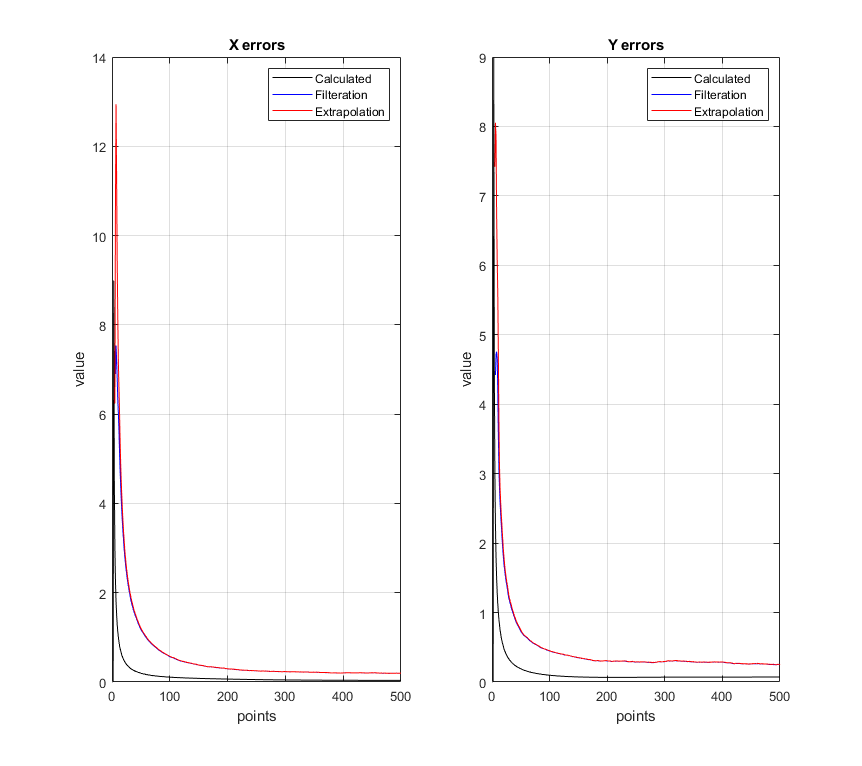

% plotting errors
figure(4)
subplot(1,2,1)
plotErr(ErrX,ErrXE,px,'X')
subplot(1,2,2)
plotErr(ErrY,ErrYE,py,'Y')

**Comment:**

In the figure shown above, for the X position,  true estimation errors of filteration and extrapolation are  settling at a value of ~0.19, higher than the calulculated error of 0.04, but still much lower compared to the previous case with GPS data only. This proves that the odometry data were more accurate and closer to the true trajectory and thus relying on both data reslted in much better results.  The same results appear for the Y position as true estimation errors of filteration and extrapolation are  settling at a value of ~0.27, higher than the calulculated error of 0.07, but still much lower compared to the previous case with GPS data only. 

# Learning Log:

In this assignment we develop a navigation filter by assimilating data coming from different sources at the same time using nonlinear model (Extended Kalman filter). Eventually we summarized what we learnt in the following:

- Simultaneously using both measurment sources, resulted in much better results and effective filteration.

- In real applications it is much better not to put all of our trust in a single sensor as it might not work properly at some point, or get affected by some eviromental factors, but to use multiple sensors(observers) and fusing their observations giving them different weights dependng on how much we trust each one.